% I-d curves for anterior (corrected for space clamp) vs. posterior

%%Import data and metadata
ephysData = ImportPatchData('incl',1);
projects = {'FAT';'SYM'};
ephysData = FilterProjectData(ephysData, projects);
clear projects;

ephysMetaData = ImportMetaData();  %Recording Database.xlsx
attenuationData = ImportMetaData(); %AttenuationCalcs.xlsx

%% Analyze capacity transient for C, Rs, and tau

ephysData = CtAnalysis(ephysData);

clear lastfit;

%% Select recordings that match parameters based on metadata

strainList = {'TU2769'};
internalList = {'IC2'};
stimPosition = {'posterior'};

wormPrep = {'dissected'};
cellDist = [40 200]; % stimulus/cell distance in um
resistCutoff = '<250'; % Rs < 250 MOhm
extFilterFreq = 2.5; % frequency of low-pass filter for stimulus command

posteriorDistCells = FilterRecordings(ephysData, ephysMetaData,...
    'strain', strainList, 'internal', internalList, ...
    'stimLocation', stimPosition, 'wormPrep', wormPrep, ...
    'cellStimDistUm',cellDist, 'RsM', resistCutoff, ...
    'stimFilterFrequencykHz', extFilterFreq);

excludeCells = {'FAT180','FAT181'}; %excluded bc gonad dissection was on the wrong side
%TODO: make column in recording database for record exclusion, check against that
%in FilterRecordings.
posteriorDistCells = posteriorDistCells(~ismember(posteriorDistCells,excludeCells));

stimPosition = {'anterior'};

anteriorDistCells = FilterRecordings(ephysData, ephysMetaData,...
    'strain', strainList, 'internal', internalList, ...
    'stimLocation', stimPosition, 'wormPrep', wormPrep, ...
    'cellStimDistUm',cellDist, 'RsM', resistCutoff, ...
    'stimFilterFrequencykHz', extFilterFreq);


clear cellDist strainList internalList cellTypeList stimPosition resistCutoff ans wormPrep excludeCells;

% This results in a file with three columns: cell ID, series, and sweeps 
% that have been approved for analysis use.

%% Visual/manual exclusion of bad sweeps 
% This is mainly based on excluding sweeps with leak > 10pA, but also
% sweeps where the recording was lost partway through or some unexpected
% source of noise was clearly at play.

protList ={'WC_Probe';'NoPre'};
matchType = 'first';

% ExcludeSweeps(ephysData, protList, anteriorDistCells, 'matchType', matchType);
% ExcludeSweeps(ephysData, protList, posteriorDistCells, 'matchType', matchType);

%% Find MRCs
sortSweeps = {'magnitude','magnitude','magnitude','magnitude'};

anteriorMRCs = IdAnalysis(ephysData,protList,anteriorDistCells,'num','matchType',matchType, ...
    'tauType','thalfmax', 'sortSweepsBy', sortSweeps, 'integrateCurrent',1 , ...
    'recParameters', ephysMetaData,'sepByStimDistance',1);


posteriorMRCs = IdAnalysis(ephysData,protList,posteriorDistCells,'num','matchType',matchType, ...
    'tauType','thalfmax', 'sortSweepsBy', sortSweeps, 'integrateCurrent',1 , ...
    'recParameters', ephysMetaData,'sepByStimDistance',1);


clear protList sortSweeps matchType

%% Pull out and combine relevant data for plot

% Voltage attenuation data comes from the length constant fitting done in
% Igor, which gives a voltage attenuation factor at the location of the
% stimulus site for each recording, based on the calculated length
% constant.

% Grab the current at the selected step size (e.g., 10um) for each
% recording, grab the cell-stimulus distance for that recording, and match
% the recording name against the voltage attenuation table to find the
% attenuation factor for that recording.
whichMRCs = anteriorMRCs;
thisAtt = attenuationData(:,[2 10]);
distVPeak = [];
stepSize = 10;

for iCell = 1:size(whichMRCs,1)
    thisCell = whichMRCs{iCell,3};
    whichStep = round(thisCell(:,1)) == stepSize;
    if any(whichStep)
        thisName = whichMRCs{iCell,1};
        hasAtt = strcmp(thisName,thisAtt(:,1));
        
        if any(hasAtt)
            distVPeak(iCell,:) = [thisCell(whichStep,[11 6]) thisAtt{hasAtt,2}];
        else
            distVPeak(iCell,:) = [thisCell(whichStep,[11 6]) nan];
        end
        
    end
    
end

distVPeak_Ant = distVPeak;

whichMRCs = posteriorMRCs;
distVPeak = [];


for iCell = 1:size(whichMRCs,1)
    thisCell = whichMRCs{iCell,3};
    whichStep = round(thisCell(:,1)) == stepSize;
    if any(whichStep)
        thisName = whichMRCs{iCell,1};
        hasAtt = strcmp(thisName,thisAtt(:,1));
        
        if any(hasAtt)
            distVPeak(iCell,:) = [thisCell(whichStep,[11 6]) thisAtt{hasAtt,2}];
        else
            distVPeak(iCell,:) = [thisCell(whichStep,[11 6]) nan];
        end
        
    end
    
end

distVPeak_Post = distVPeak;

clear a iCell thisCell whichMRCs whichStep thisName hasAtt distVPeak

%% Make correction to I for space clamp error
% (Note: this is an approximation, assuming that the majority of the
% current is happening at the stimulus site, which we know is not entirely
% true, and channels at different points along the neurite will experience
% different voltages.

% Now calculate what the actual voltage was at the stimulus site based on
% the voltage attenuation factor. In this case, command voltage was -60mV
% for all steps. 

% attenuation factor = Vm'/Vc so Vm' = Vc * attenuation factor
 
% Then calculate what current would've been based on sodium reversal
% potential. 
% For IC2 solution used here, Ena = +94mV.
 
% Im' = Im * ((Vc-Ena)/(Vm'-Ena))
 
Vc = -0.06; %in V
Ena = 0.094; % in V
Im = distVPeak_Ant(:,2);
Vatt = distVPeak_Ant(:,3);

Vm = Vc * Vatt;
distVPeak_Ant(:,4) = (Im * (Vc-Ena)) ./ (Vm-Ena);

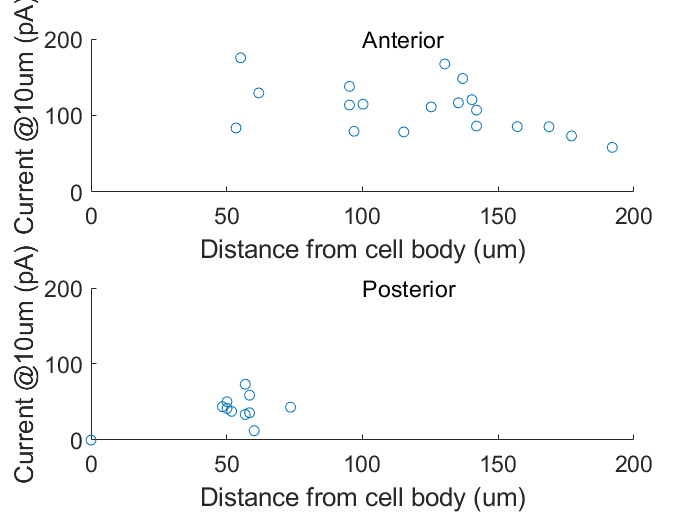

%% Plot anterior and posterior on separate plots

figure(); axh(1) = subplot(2,1,1);
scatter(distVPeak_Ant(:,1),distVPeak_Ant(:,4));
xlabel('Distance from cell body (um)');
ylabel('Current @10um (pA)')
text(100,200,'Anterior');
axh(2) = subplot(2,1,2);
scatter(distVPeak_Post(:,1),distVPeak_Post(:,2));
xlabel('Distance from cell body (um)');
ylabel('Current @10um (pA)')
text(100,200,'Posterior');

xlim(axh,[0 200]); ylim(axh,[0 200]);